clear all; close all; clc;
rng(41137)

# Digital transmission: Baseband PAM (Pulse Amplitude Modulation), Pulse‐shaping and Eye‐ diagrams

## 1.SYMBOLS AND SINC‐PULSE

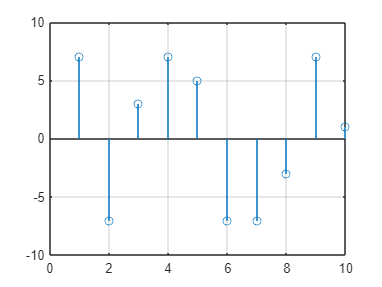

alphabet = -7:2:7; % Symbol alphabet for 4-PAM
N_symbols = 10;
% Random vector that includes integers (=”symbol indices”) between 1 and 4:
symbol_ind = randi(length(alphabet),1,N_symbols);
% I.e., these numbers represent the symbols indices in the alphabet
% (1 means the symbol "-3", 2 means the symbol "-1", and so on...
symbols = alphabet(symbol_ind); % Generate a random symbol sequence
figure
stem(symbols); % Plots the symbol sequence
grid on

### 1.2. ILLUSTRATION OF A BASEBAND SIGNAL BY USING SIC‐PULSES

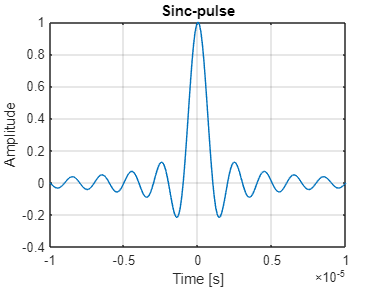

r = 10;                % samples per pulse/symbol (oversampling factor) 
T = 1e-6;              % Symbol time interval [s].  
Fs = r/T;              % Sampling frequency 
Ts = 1/Fs;             % Sample time interval  
t = 0:Ts:N_symbols*T;  % Time vector (sampling intervals) for all symbols 
% Generation of the pulse: 

% Option #1 (traditional) 
% p = sinc(t/T); % The pulse given in fixed time vector defined by t 
 
% Option #2 (The pulse given in function defined by the time vector 
% parameter t. In Matlab this is called a handle function and it is more 
% convenient in our case, so we use it in the following. Here p is not a 
% double-variable, but it is a function that can be called any time for 
% different time vectors)
p = @(t) sinc(t/T); % Sinc pulse handle function
t_plot = -10e-6:Ts:10e-6; %plot time interval 
 
figure 
plot(t_plot,p(t_plot)) 
xlabel('Time [s]') 
ylabel('Amplitude') 
grid on 
xlim([-10e-6 10e-6]) % x-axis limits 
title('Sinc-pulse')

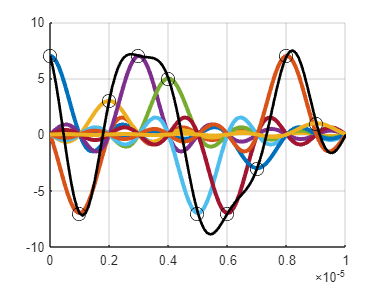


figure 
hold on % allows us to plot on top of the previous plots 
x = 0; %initialize the sum of pulses (i.e. the total signal x(t)) 
a = symbols; % Renaming the symbol vector according to the equation notation 
% For each symbol index k, we generate the weighted pulse and add it to the 
% overall sum defining the PAM signal x 
for k = 0:N_symbols-1 
 
    % Remember that Matlab indexing starts from 1 (a_0=a(1), a_1=a(2), etc.) 
 
    kth_pulse = a(k+1)*p(t-k*T); %kth pulse weighted by the symbol a_k 
     
 
    x = x + kth_pulse; % add the kth pulse to the overall sum (PAM signal) 


    plot(t,kth_pulse,'LineWidth',3)  
  
    % Notice that Matlab changes the line color automatically between plots 
end

plot(t,x,'k','LineWidth',2) % Plotting the total signal x with black color 

 
% In the end, we also plot the symbol values in their correct time instants 
plot(0:T:T*(N_symbols-1),symbols(1:N_symbols),'ko','MarkerSize',10) 

hold off 
grid on

## 2. BASEBAND SIGNAL BY USING A RAISED‐COSINE PULSE

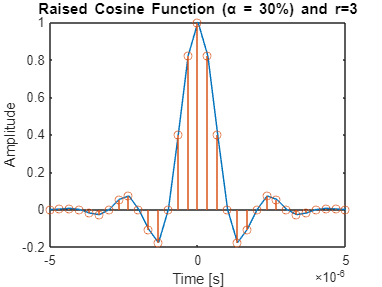

%Generating 500 PAM symobls 
N_symbols = 500;
symbol_ind = randi(length(alphabet),1,N_symbols);
% I.e., these numbers represent the symbols indices in the alphabet
% (1 means the symbol "-3", 2 means the symbol "-1", and so on...
symbols = alphabet(symbol_ind); % Generate a random symbol sequence


r = 3;             % Oversampling factor 
T = 1e-6;          % Symbol time interval [s].  
Fs = r/T;          % Sampling frequency 
Ts = 1/Fs; % Sampling time 
t = -5*T:Ts:5*T; % Time vector (sampling intervals) for one pulse 

alfa = 0.3; % Roll-off factor


% Raised-Cosine FIR filter: 
p = sinc(t/T).*((cos(alfa*pi*t/T))./(1-((2*alfa*t/T).^2)));  

figure 
plot(t,p)
hold on 
stem(t,p) 
xlabel('Time [s]') 
ylabel('Amplitude') 
title('Raised Cosine Function (\alpha = 30%) and r=3')
hold off

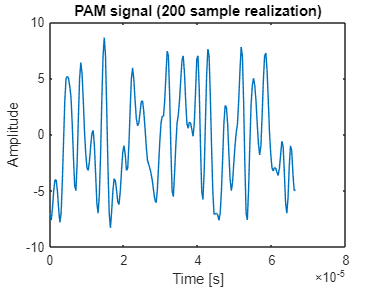


% Zero vector initialized for Up-sampled symbol sequence 
symbol_upsampled = zeros(size(1:r*N_symbols));  
 
% Up-sampled sequence, i.e. a1, 0, 0, a2, 0, 0, a3, 0, 0, a4, 0, ... 
symbol_upsampled(1:r:r*N_symbols) = symbols;  
 
% Transmitter filtering      
xn = filter(p,1,symbol_upsampled);                 
 
% Remove filter delay. In general it is the sample index of the the maximum 
% value of the impulse response. Thus, check "figure,stem(1:length(p),p)", 
% where the maximum is at the 16th sample. Thus, the first symbol 
% corresponds the 16th sample 
filter_delay = (length(p)-1)/2; 
xn = xn(filter_delay+1:end);
figure 
plot(0:Ts:199*Ts,xn(1:200)) % Plotting a piece of the generated signal 
xlabel('Time [s]') 
ylabel('Amplitude')
title('PAM signal (200 sample realization)')

## 3 EYE‐DIAGRAM AND SPECTRAL CONSIDERATIONS

### 3.1 PLOTTING THE EYE DIGRAM and Noisy Signal

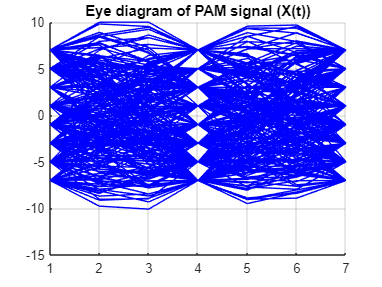

figure 
hold on 
for i = 1:2*r:(length(xn)-2*r) 
    plot(xn(i:i+2*r),'b'); 
end 
hold off
title('Eye diagram of PAM signal (X(t))')
grid on


SNR_target = 15; % SNR in dB  
zn = randn(size(xn));       % White Gaussian random noise  
%Signal power 
P_xn = var(xn);             % relies on the ergodicity of the signal model
% P_xn = mean(abs(xn).^2);  % exact power for this realization 
 
%Noise power 
P_zn = var(zn);             % relies on the ergodicity of the signal model 
noise_scaling_factor = sqrt(P_xn/P_zn/10^(SNR_target/10)); 
 
% Noisy signal 
yn = xn + noise_scaling_factor*zn; 
 
% Make sure that the SNR is OK (just in case…): 
P_zn_scaled = var(noise_scaling_factor*zn);  
SNR_check = 10*log10(P_xn/P_zn_scaled)

SNR_check = 15

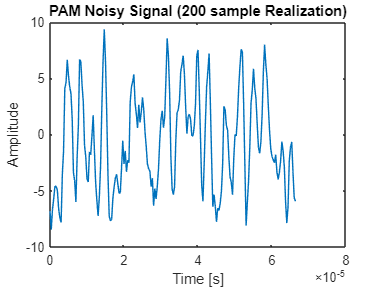


figure 
plot(0:Ts:199*Ts,yn(1:200)) % Plotting first 200 samples noisy signal 
xlabel('Time [s]') 
ylabel('Amplitude')
title('PAM Noisy Signal (200 sample Realization)')

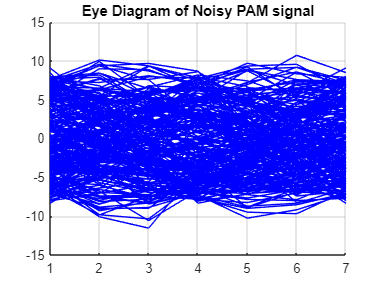


% Plotting eye diagram of noisy signal 
figure 
hold on 
for i = 1:2*r:(length(yn)-2*r) 
    plot(yn(i:i+2*r),'b'); 
end 
hold off 
title('Eye Diagram of Noisy PAM signal')
grid on

### 3.2 SIGNAL SPECTRUM AND PULSE SPECTRUM

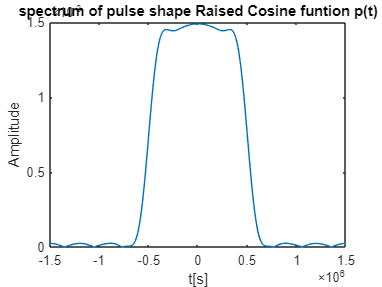

n = 2048;
F_p=fft(p,n);                         % DFT of p, saved to F_p  
Np=length(F_p);  
F0=1/(Ts*Np);                       % frequency resolution. 
freq2=-Np/2*F0:F0:(Np/2-1)*F0;
%freq2=-N/2*F0:F0:(N/2-1)*F0;% Two-sided frequency Axis  
figure 
plot(freq2,fftshift(abs(F_p)/n))
title('spectrum of pulse shape Raised Cosine funtion p(t)')
xlabel('t[s]')
ylabel('Amplitude')

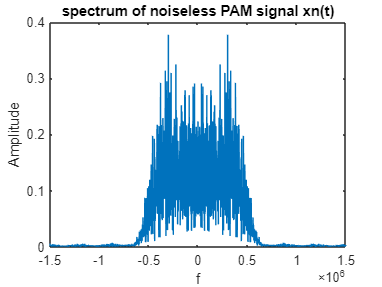


F_xn=fft(xn,n);                         % DFT of p, saved to F_p  
Nxn=length(F_xn);  
F0=1/(Ts*Nxn);                       % frequency resolution. 
freq2=-Np/2*F0:F0:(Np/2-1)*F0;
%freq2=-N/2*F0:F0:(N/2-1)*F0;% Two-sided frequency Axis  
figure 
plot(freq2,fftshift(abs(F_xn)/n))
title('spectrum of noiseless PAM signal xn(t)')
xlabel('f')
ylabel('Amplitude')

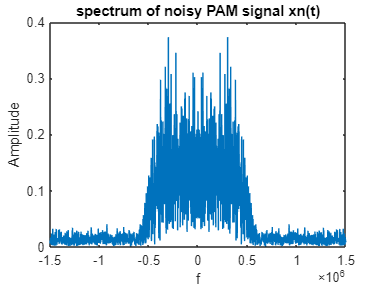


F_yn=fft(yn,n);                         % DFT of p, saved to F_p  
Nyn=length(F_yn);  
F0=1/(Ts*Nyn);                       % frequency resolution. 
freq2=-Np/2*F0:F0:(Nyn/2-1)*F0;
%freq2=-N/2*F0:F0:(N/2-1)*F0;% Two-sided frequency Axis  
figure 
plot(freq2,fftshift(abs(F_yn)/n))
title('spectrum of noisy PAM signal xn(t)')
xlabel('f')
ylabel('Amplitude')

## 3.3 MODIFYING THE SYSTEM PARAMETER

%Done Inside Code by Conrolers